alpha= 1+mod(230,3)

alpha = 3


%Question-1

% Filter specifications
 % maximum passband ripple in dB
f_p = 10;  % passband edge frequency
f_s = 20;  % stopband edge frequency 
fs = 720;  % sampling frequency in samples/sec
attenuation = 40;  % minimum stopband attenuation in dB
sos = tf(z,p,1/fs);
sos

sos =
 
  1.254e-08 z^5 + 6.271e-08 z^4 + 1.254e-07 z^3 + 1.254e-07 z^2 + 6.271e-08 z + 1.254e-08
  ---------------------------------------------------------------------------------------
                 z^5 - 4.929 z^4 + 9.727 z^3 - 9.608 z^2 + 4.75 z - 0.9402
 
Sample time: 0.0013889 seconds
Discrete-time transfer function.
Model Properties


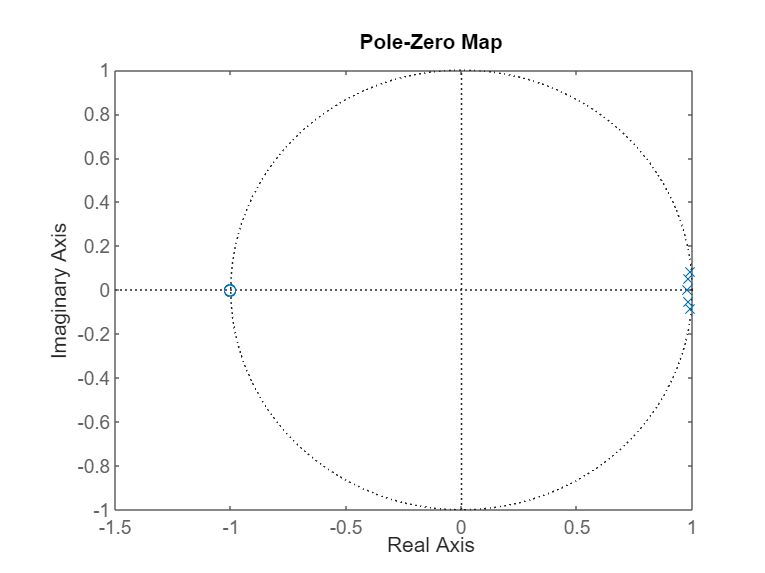

pzmap(sos)

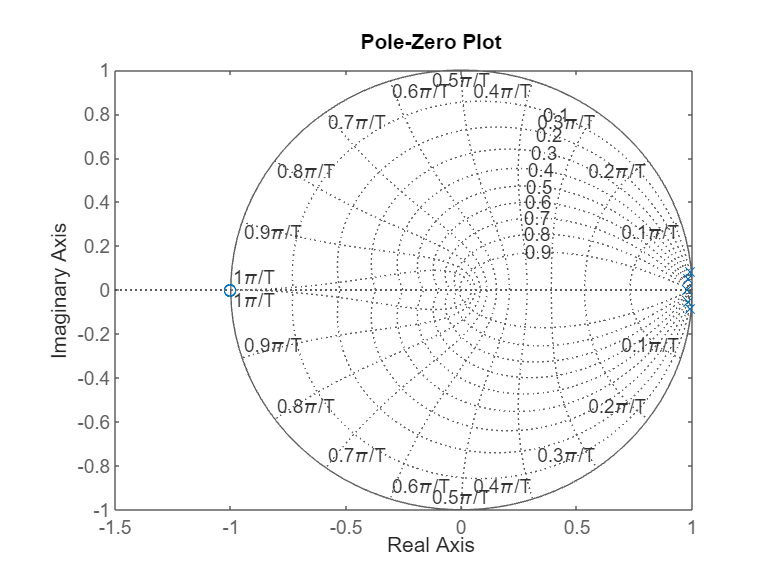

% Plot the pole-zero plot
figure;
pzmap(sos);
title('Pole-Zero Plot');
grid on;

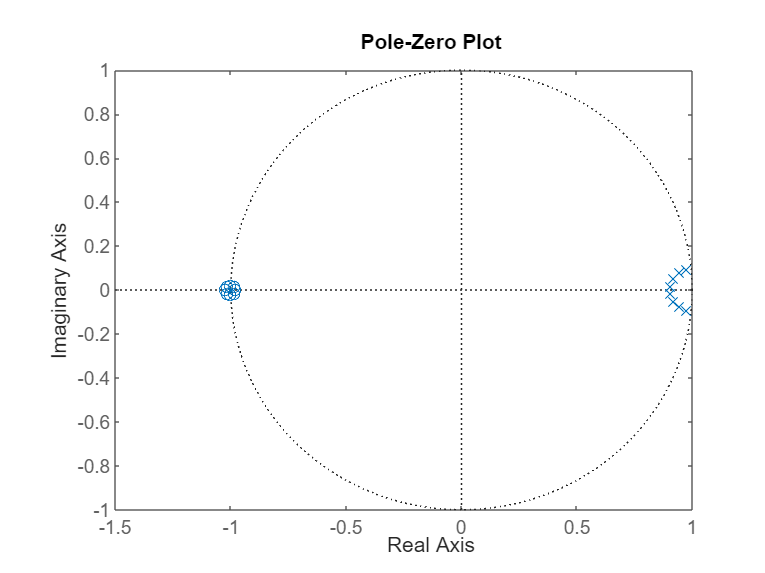

% Normalized frequencies
wp = f_p / (0.5 * fs);
ws = f_s / (0.5 * fs);

[n,Wn] = buttord(wp,ws,-2,attenuation);
[b,a]= butter(n,Wn);


H=tf(b,a,1/fs);
% Pole-zero plot
figure;
pzmap(H);
title('Pole-Zero Plot');

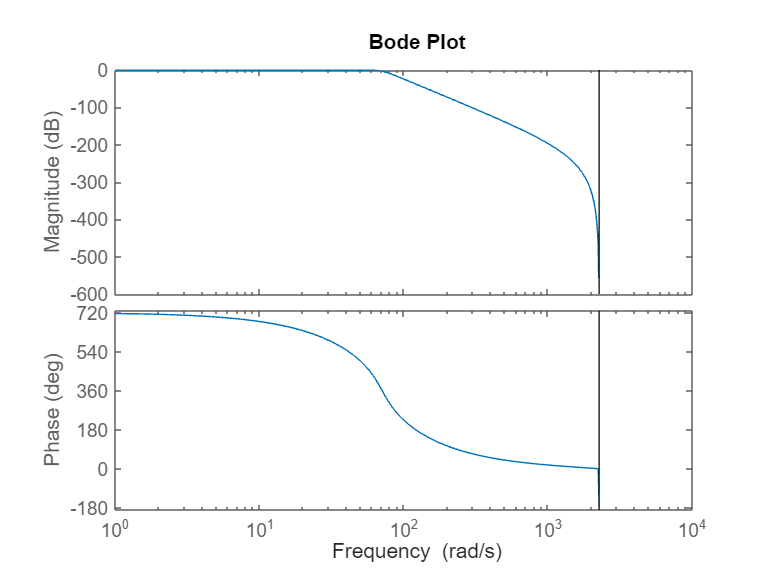


% Bode plot
figure;
bode(H);
title('Bode Plot');

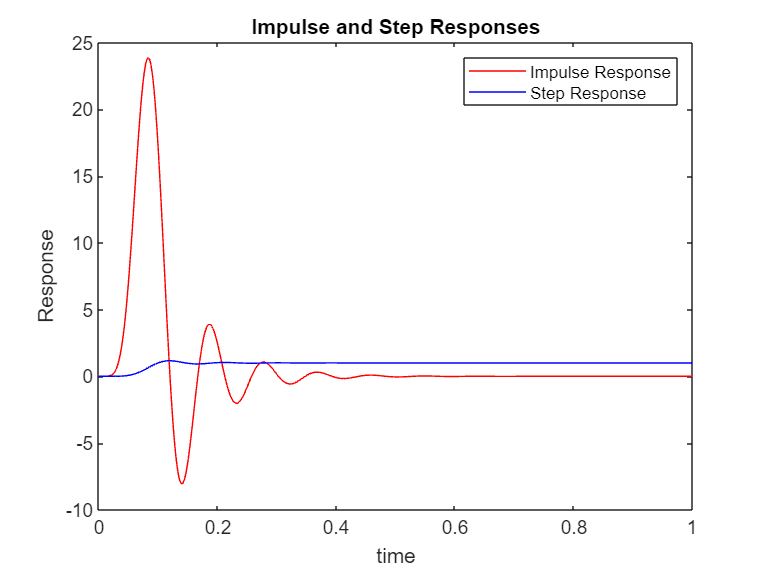


t=0:1/fs:1;

impulse_response = impulse(H, t);
step_response = step(H, t);

figure;
plot(t, impulse_response, 'r', 'DisplayName', 'Impulse Response');
ylabel('Response')
xlabel('time')

hold on;
plot(t, step_response, 'b', 'DisplayName', 'Step Response');
legend;
title('Impulse and Step Responses');
hold off

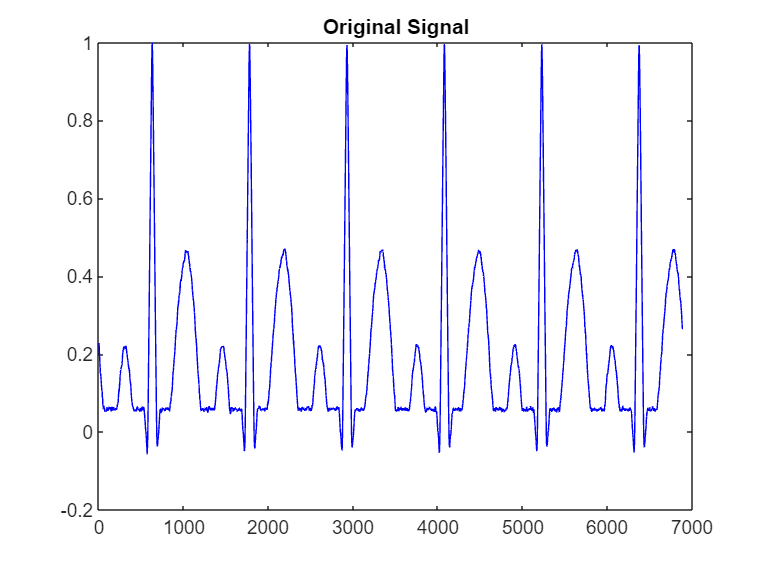

%Question-2
ecg=load("ECG_Data.txt");
filtered_ecg=filter(b,a,ecg);

figure
plot(ecg,'b','DisplayName','Original Signal')
title('Original Signal');

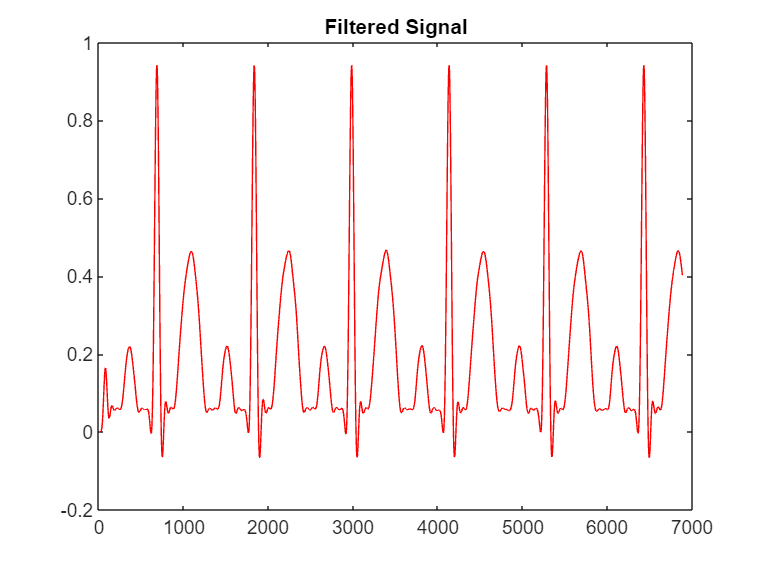

figure
plot(filtered_ecg,'r','DisplayName','Filtered Signal')
title('Filtered Signal');

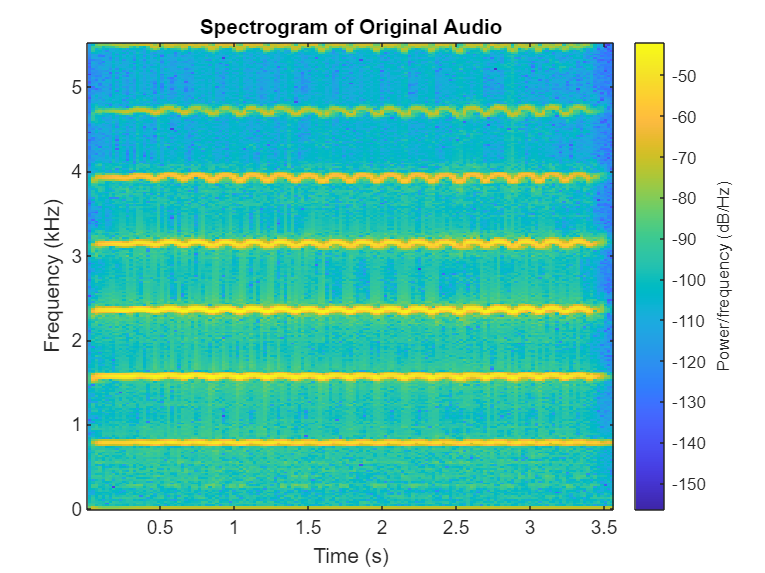

%Question-3
% Load the audio file
[y, Fs] = audioread('instru2.wav'); % Replace with your file path

% Plot the spectrogram
figure;
spectrogram(y, hamming(512), 256, 512, Fs, 'yaxis');
title('Spectrogram of Original Audio');

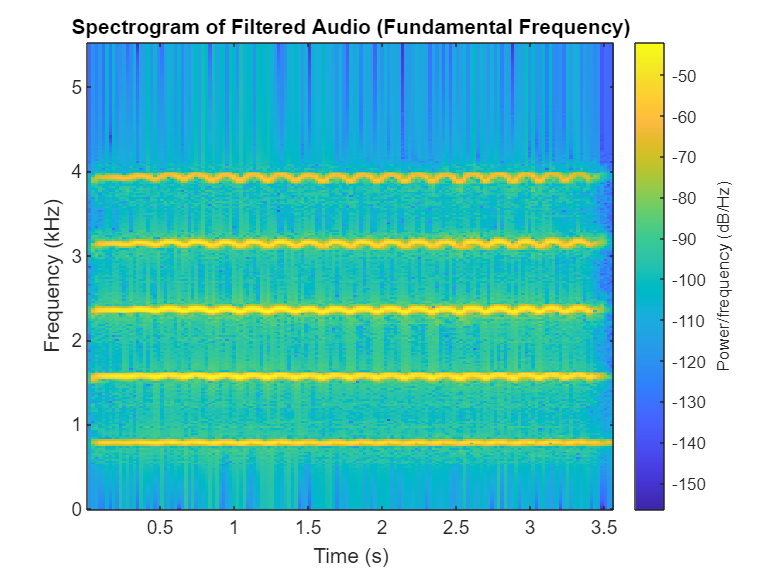


% Design a Butterworth band-pass filter
order = 10; % Filter order
Fc1 = 600; % Lower cutoff frequency in Hz (adjust as needed)
Fc2 = 4000; % Upper cutoff frequency in Hz (adjust as needed)

% Normalize cutoff frequencies
Wn1 = Fc1 / (Fs/2);
Wn2 = Fc2 / (Fs/2);

% Design the filter
[b, a] = butter(order, [Wn1, Wn2], 'bandpass');

% Apply the filter to the audio signal
filtered_signal = filter(b, a, y);

% Write the filtered signal to a new WAV file
audiowrite('filtered_signal.wav', filtered_signal, Fs);

% Plot the spectrogram of the filtered signal
figure;
spectrogram(filtered_signal, hamming(512), 256, 512, Fs, 'yaxis');
title('Spectrogram of Filtered Audio (Fundamental Frequency)');

%Question-4
% Given parameters
alpha = 2;           % Maximum passband ripple in dB
stopband_attenuation = 40; % Minimum stopband attenuation in dB
Fs = 720;            % Sampling frequency in samples/sec
Fp = 10;             % Passband edge frequency in Hz
Fstop = 20;          % Stopband edge frequency in Hz

% Calculate normalized cutoff frequencies (Wc and Ws)
Wc = 2 * Fp / Fs;
Ws = 2 * Fstop / Fs;

% Determine filter order (N) using the formula for Chebyshev Type I filter
[n, Wn] = cheb1ord(Wc, Ws, alpha, stopband_attenuation);

% Design the Chebyshev Type I filter
[z, p] = cheby1(n, alpha, Wn);
sos_chebyshev = tf(z, p, 1/Fs);

% Design the Butterworth filter as in the previous example
[n_butterworth, Wn_butterworth] = buttord(Wc, Ws, alpha, stopband_attenuation);
[z_butterworth, p_butterworth] = butter(n_butterworth, Wn_butterworth);
sos_butterworth = tf(z_butterworth, p_butterworth, 1/Fs);

% Compare the filter orders
fprintf('Chebyshev Type I Filter Order: %d\n', n);

Chebyshev Type I Filter Order: 5


fprintf('Butterworth Filter Order: %d\n', n_butterworth);

Butterworth Filter Order: 8


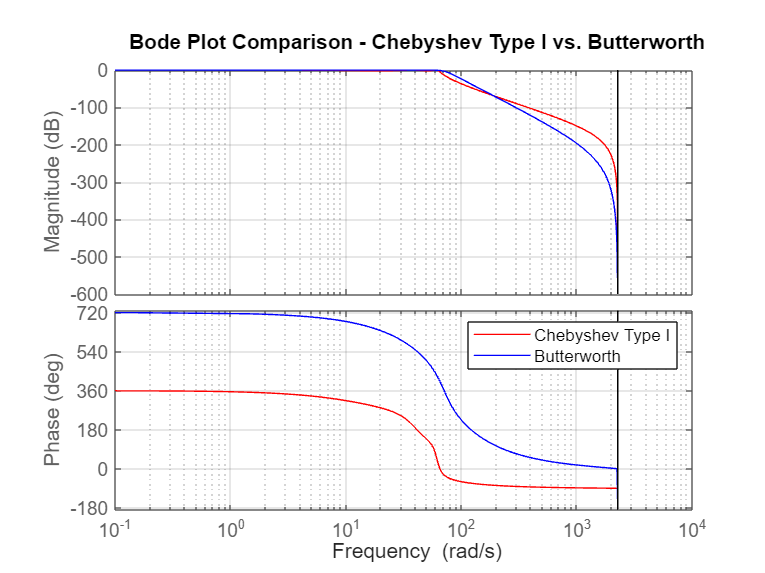


% Plot the Bode plots of Chebyshev Type I and Butterworth filters
figure;
bode(sos_chebyshev, 'r', sos_butterworth, 'b');
title('Bode Plot Comparison - Chebyshev Type I vs. Butterworth');
legend('Chebyshev Type I', 'Butterworth');
grid on;

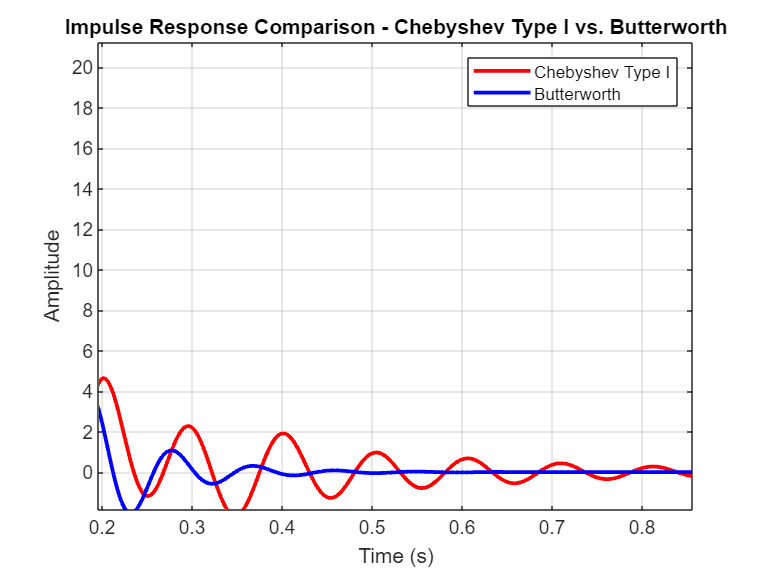


% Define the time vector for 1 second
t = 0:1/Fs:1;

% Compute the impulse response of the Chebyshev Type I filter
impulse_response_chebyshev = impulse(sos_chebyshev, t);

% Compute the step response of the Chebyshev Type I filter
step_response_chebyshev = step(sos_chebyshev, t);

% Compute the impulse response and step response of the Butterworth filter
impulse_response_butterworth = impulse(sos_butterworth, t);
step_response_butterworth = step(sos_butterworth, t);

% Plot the impulse response and step response of both filters on the same graph
figure;
plot(t, impulse_response_chebyshev, 'r', 'LineWidth', 2, 'DisplayName', 'Chebyshev Type I');
hold on;
plot(t, impulse_response_butterworth, 'b', 'LineWidth', 2, 'DisplayName', 'Butterworth');
xlabel('Time (s)');
ylabel('Amplitude');
title('Impulse Response Comparison - Chebyshev Type I vs. Butterworth');
legend('Location', 'northeast');
grid on;

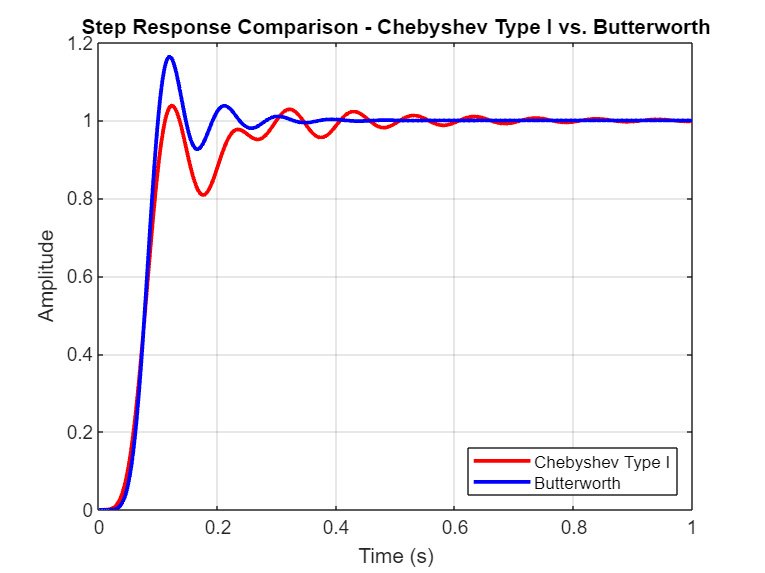


figure;
plot(t, step_response_chebyshev, 'r', 'LineWidth', 2, 'DisplayName', 'Chebyshev Type I');
hold on;
plot(t, step_response_butterworth, 'b', 'LineWidth', 2, 'DisplayName', 'Butterworth');
xlabel('Time (s)');
ylabel('Amplitude');
title('Step Response Comparison - Chebyshev Type I vs. Butterworth');
legend('Location', 'southeast');
grid on;